
Procesando archivo 1 de 15...


adrianomonster15min.txt


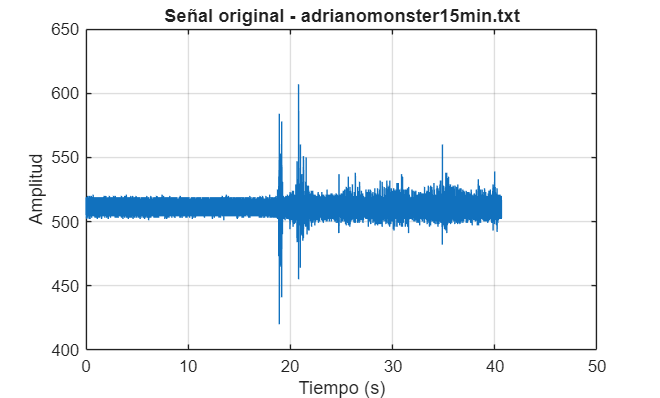

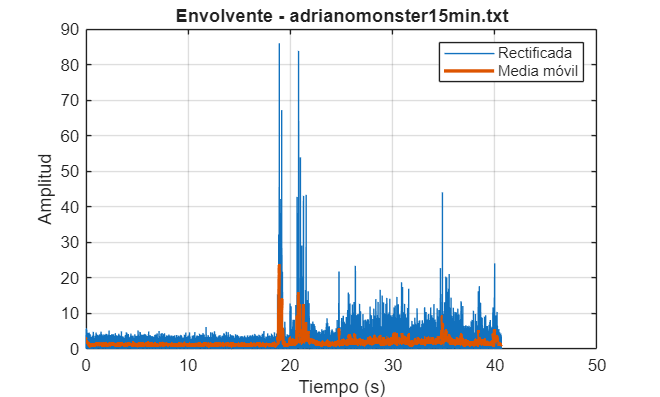

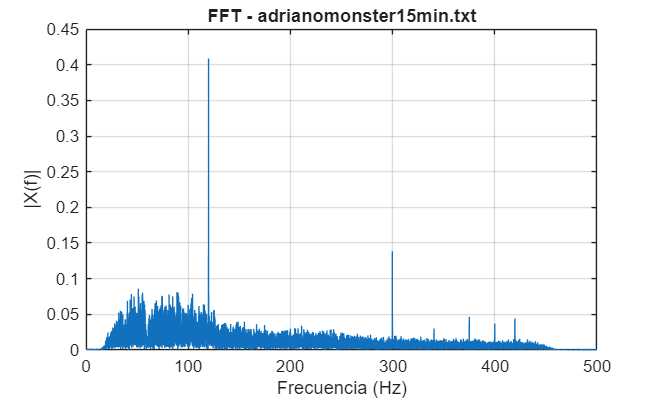

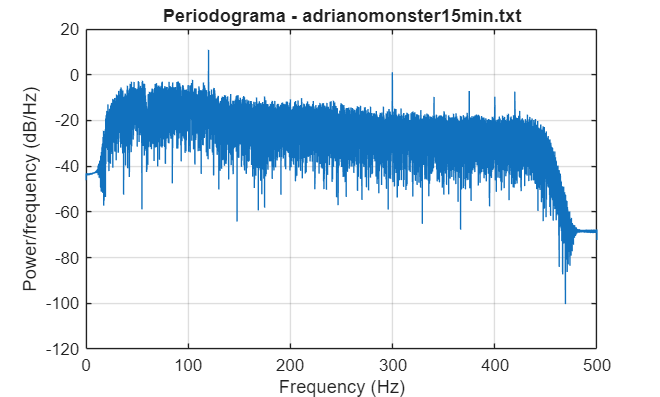

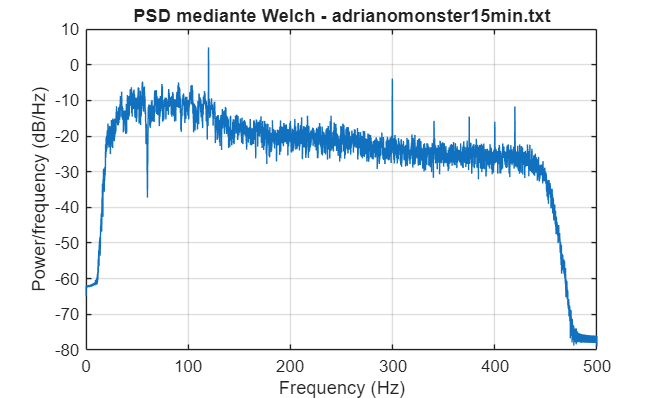

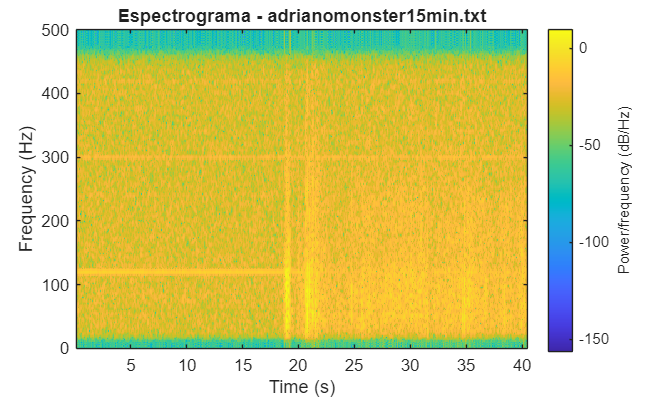

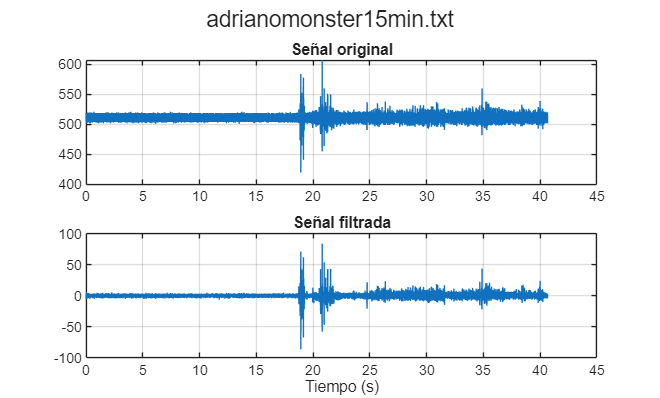


Procesando archivo 2 de 15...


adrianomonster1hr.txt


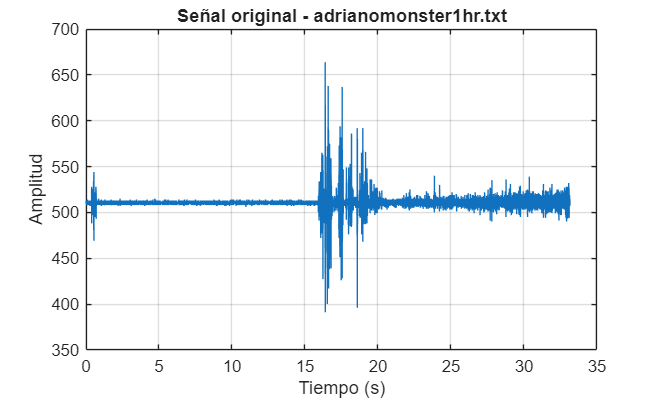

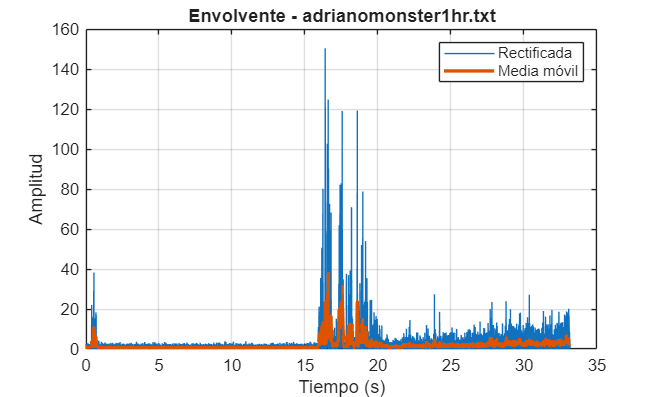

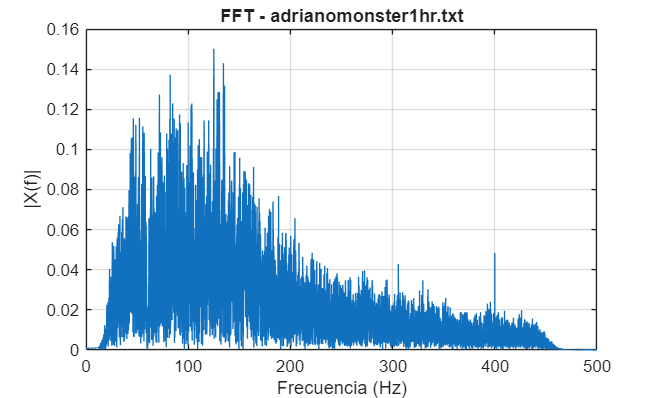

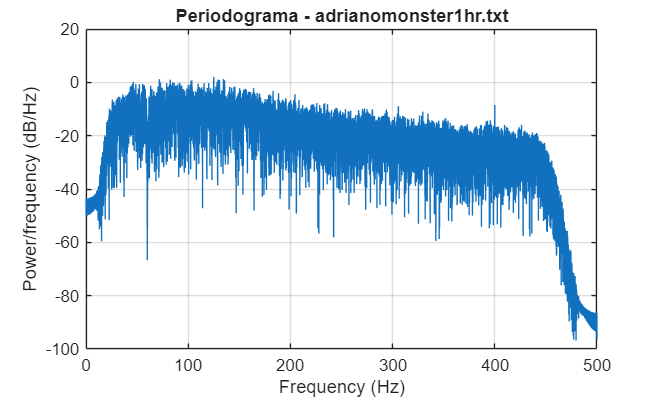

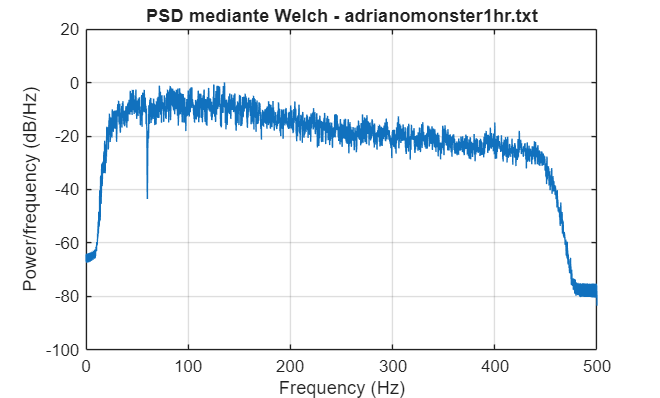

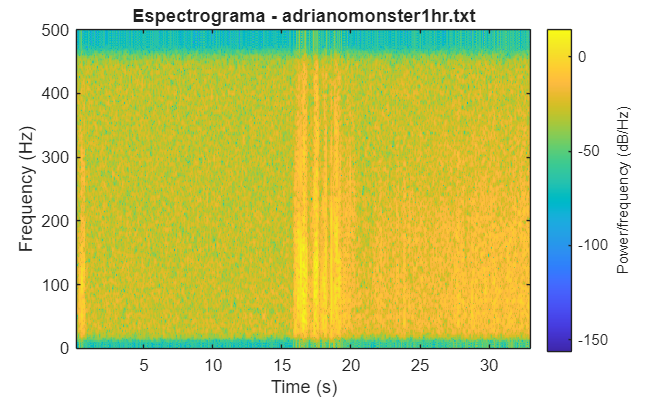

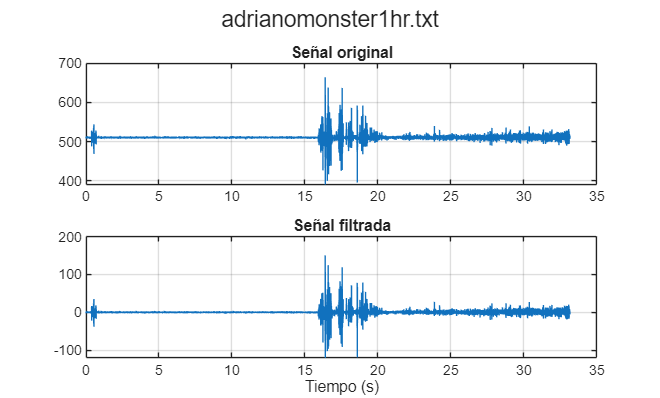


Procesando archivo 3 de 15...


basal_lapiz_adriano.txt


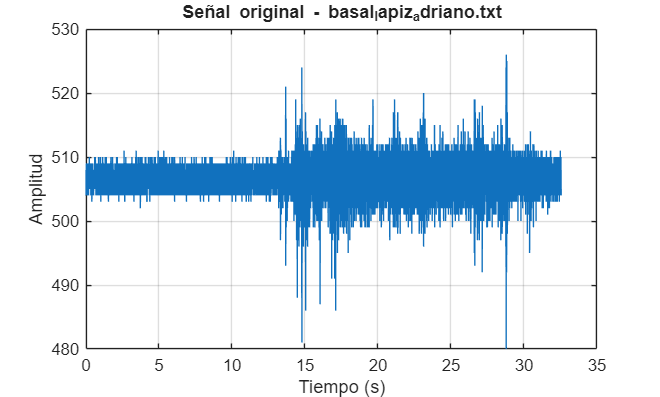

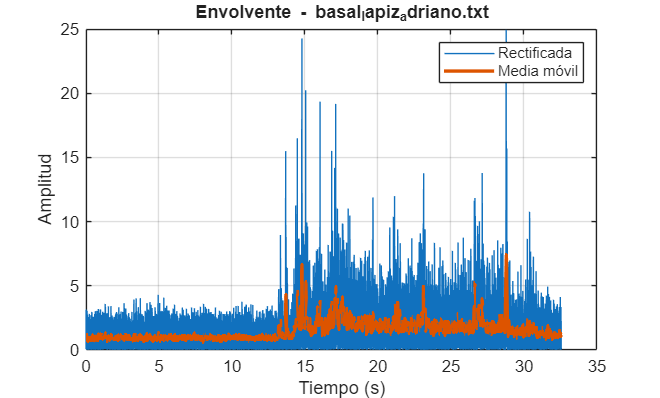

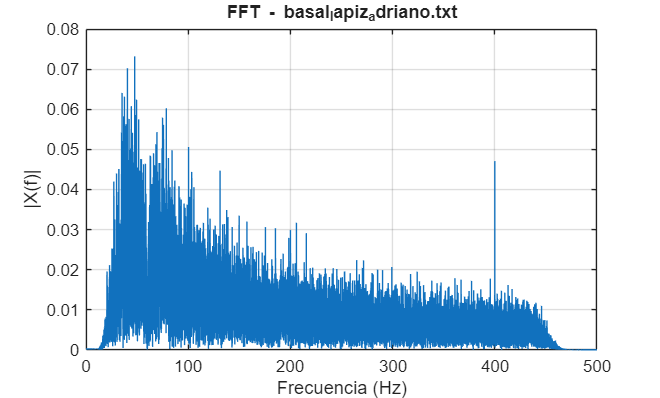

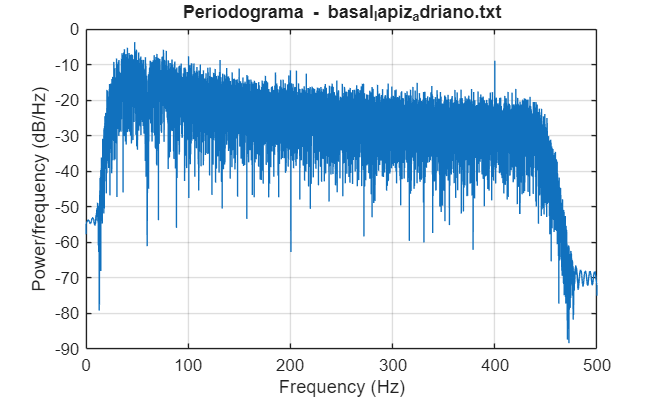

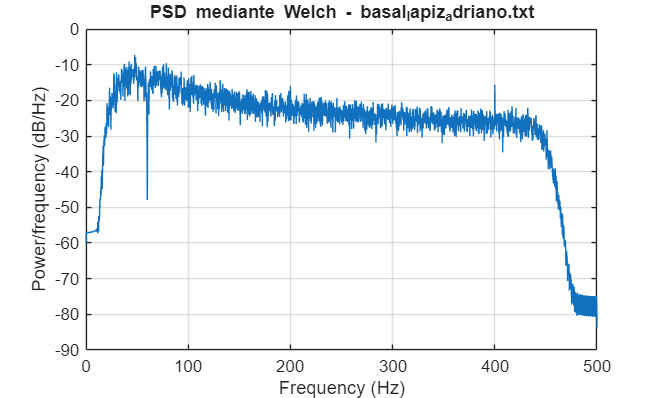

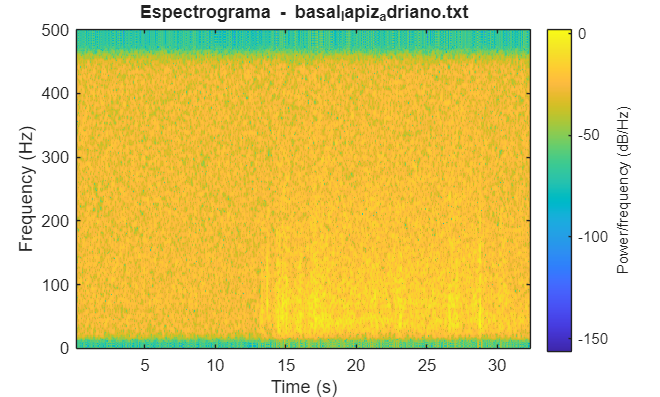

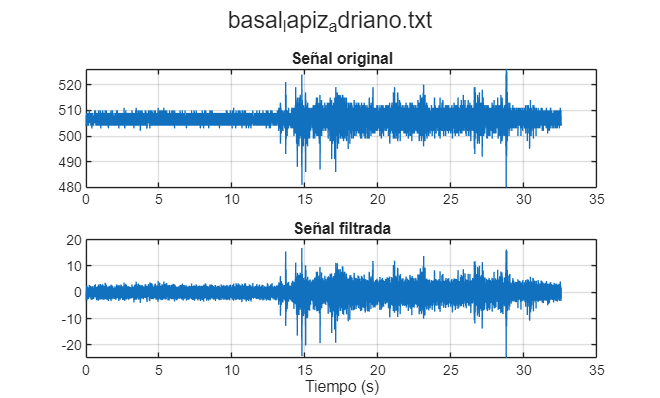


Procesando archivo 4 de 15...


basal_lapiz_anghely.txt


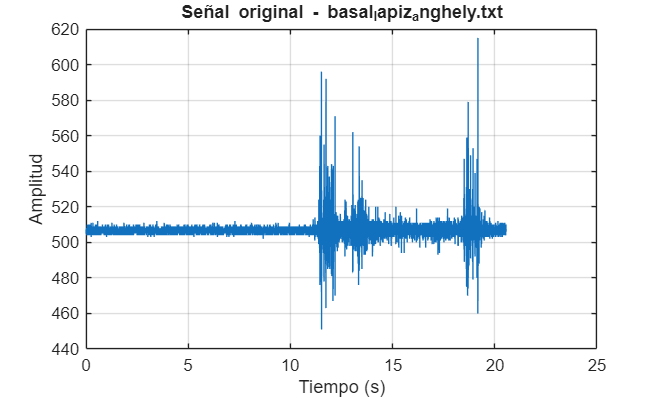

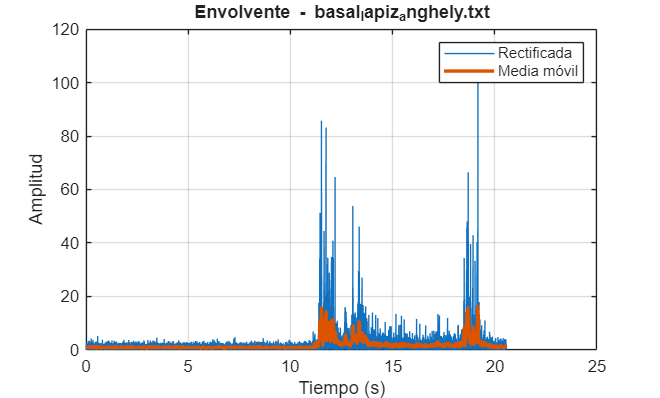

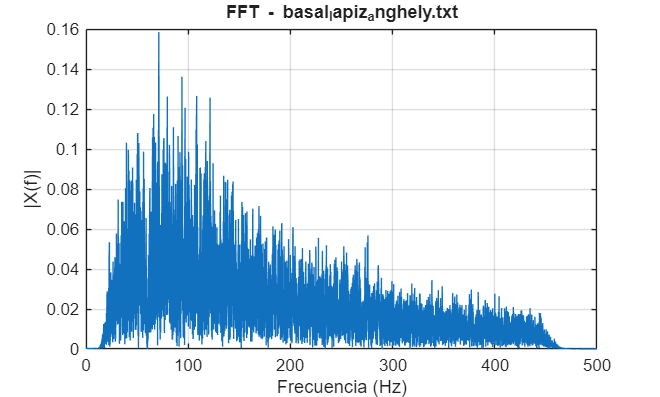

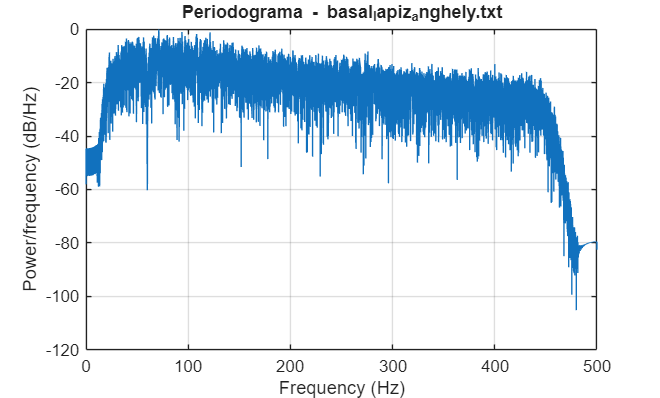

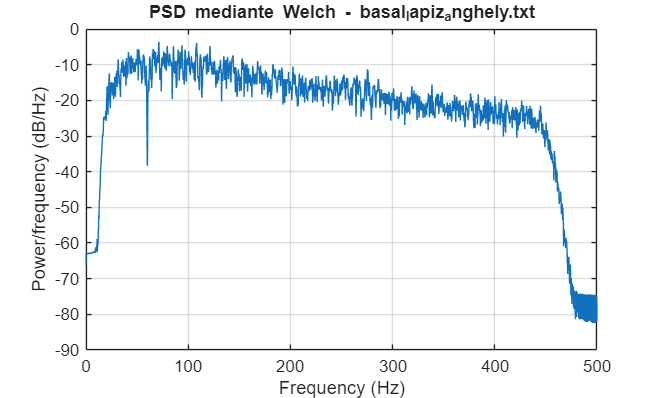

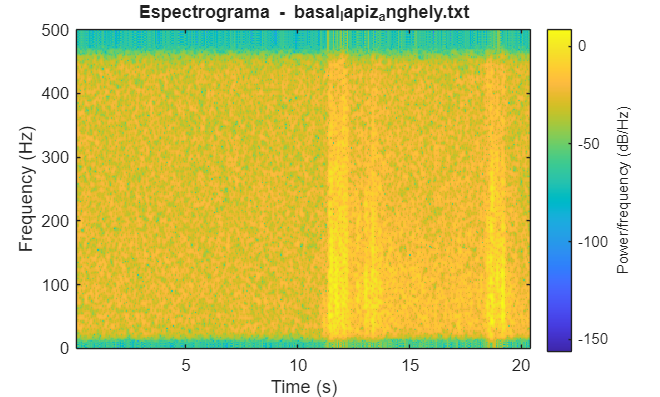

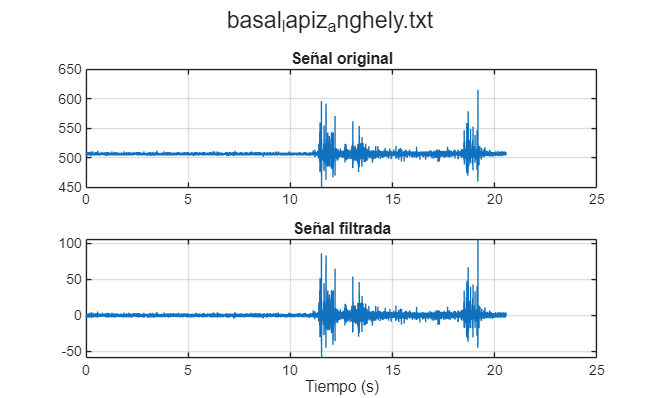


Procesando archivo 5 de 15...


basal_lapiz_ciro.txt


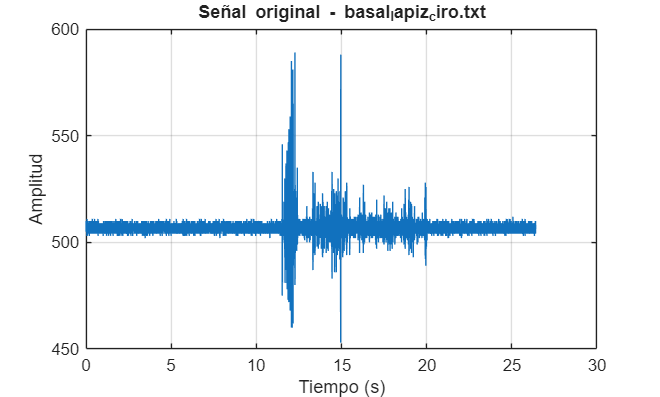

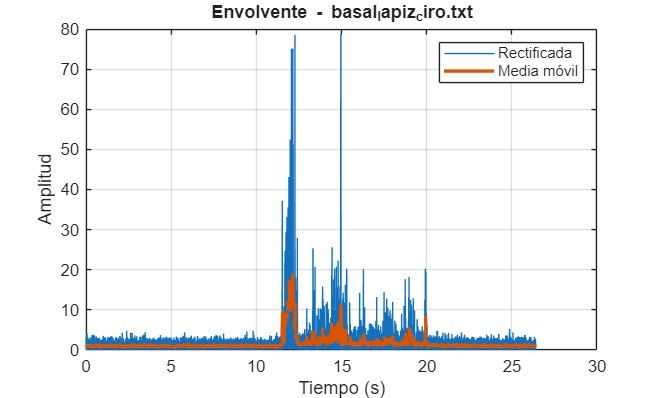

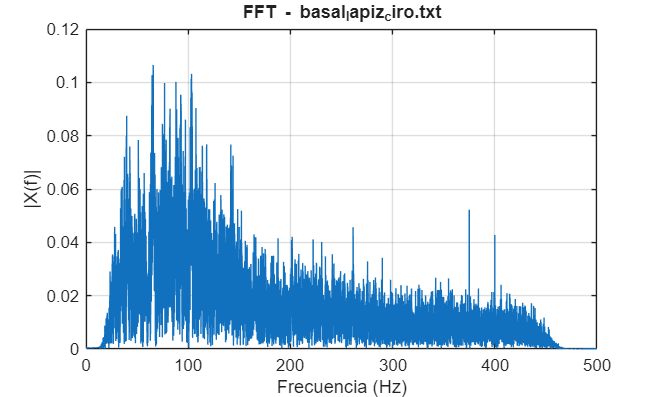

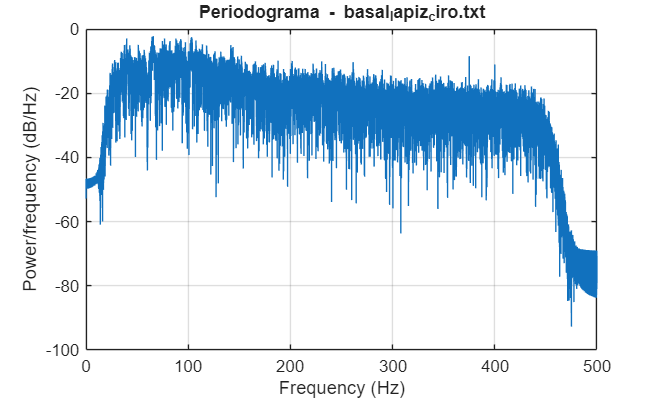

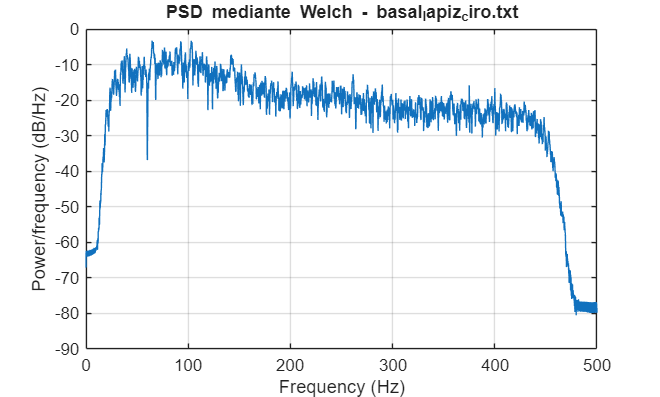

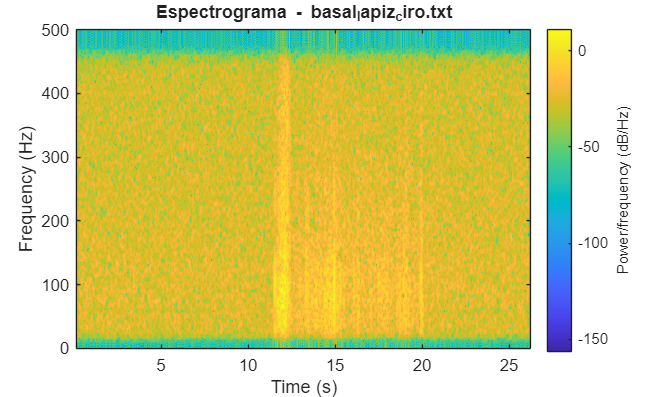

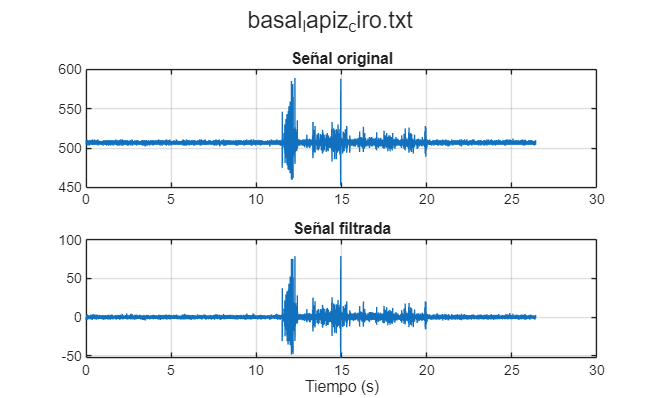


Procesando archivo 6 de 15...


basal_lapiz_daysi.txt


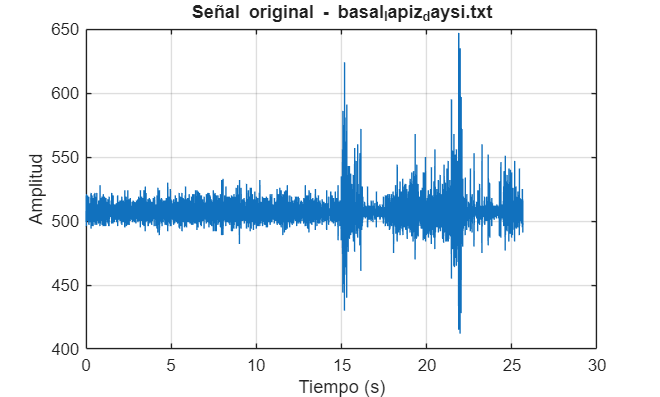

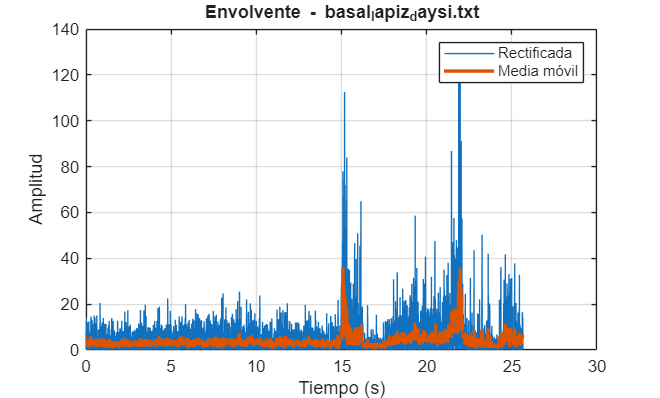

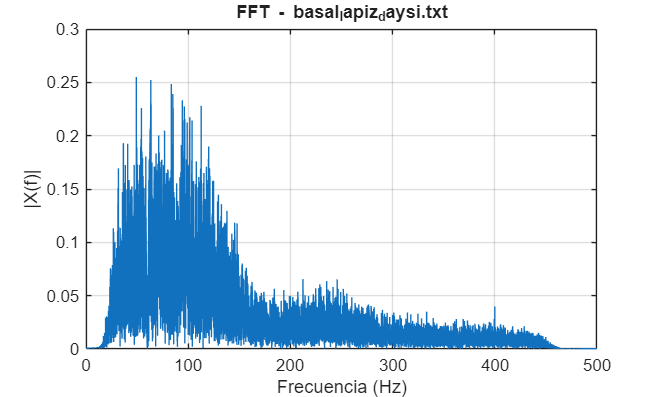

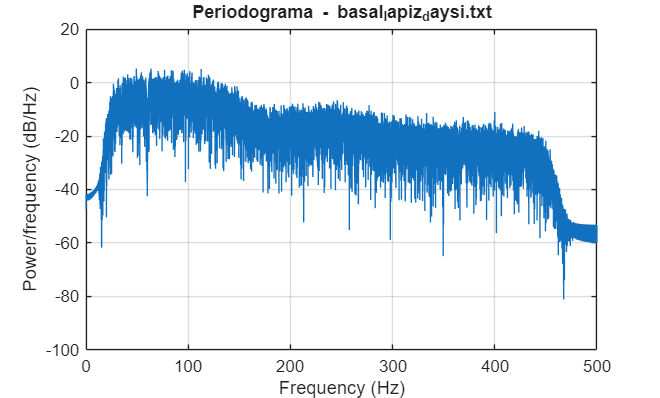

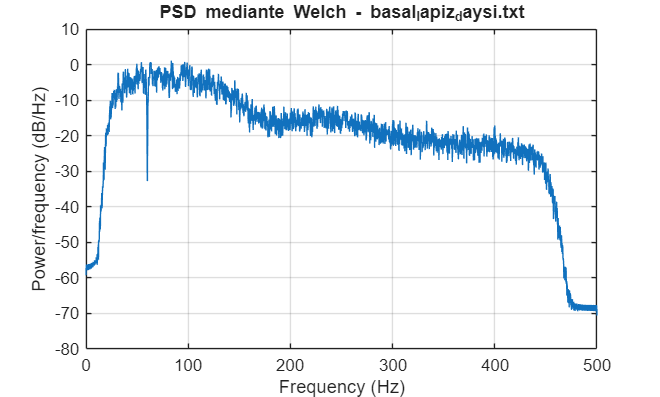

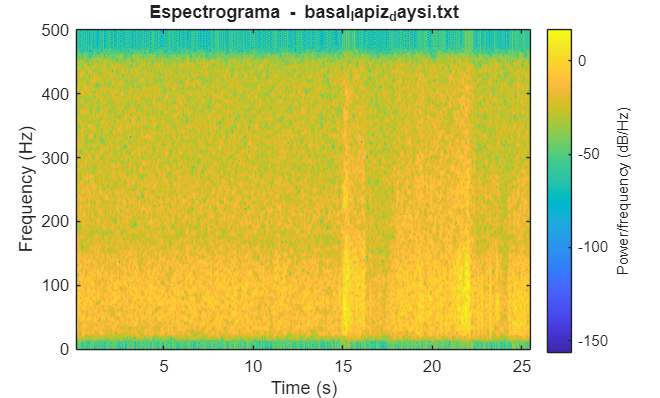

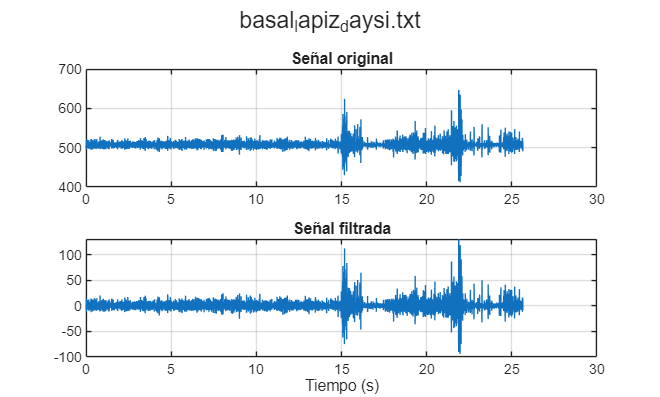


Procesando archivo 7 de 15...


basal_lapiz_gian.txt


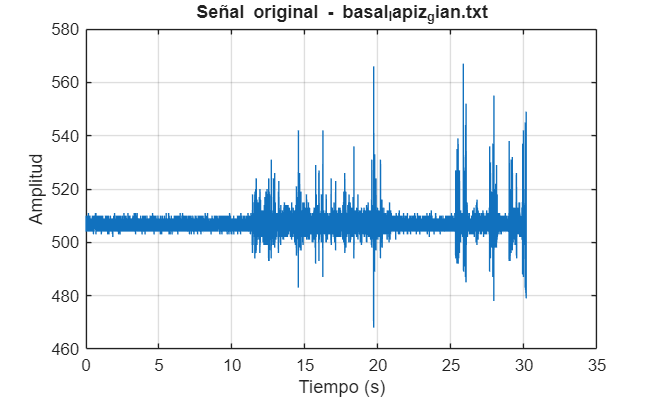

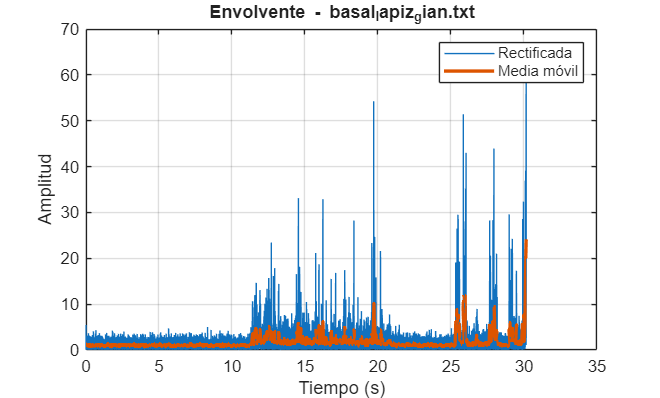

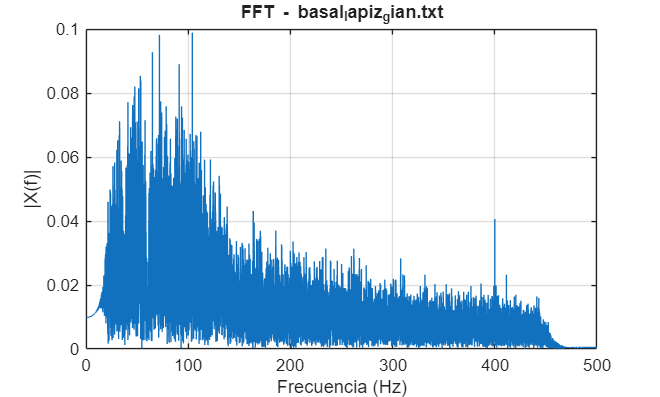

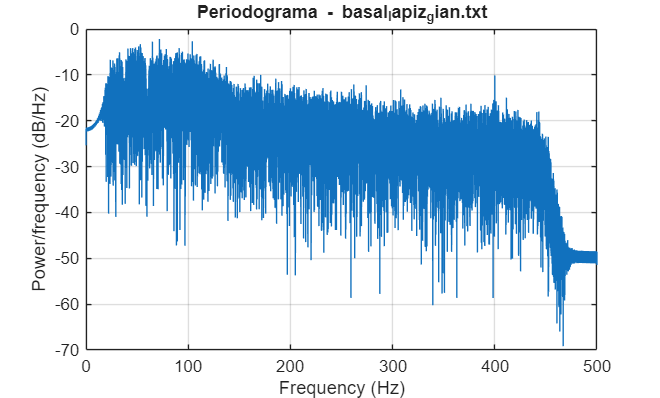

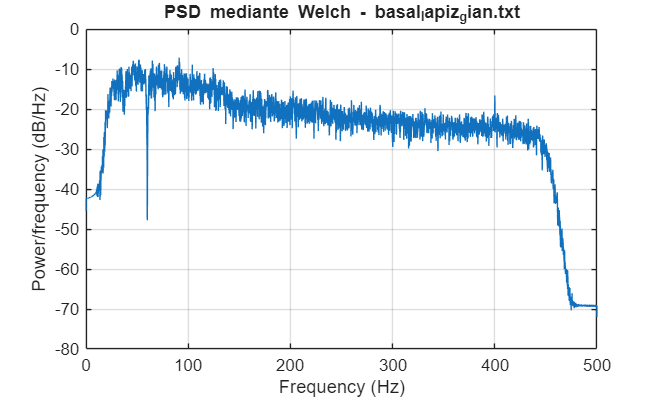

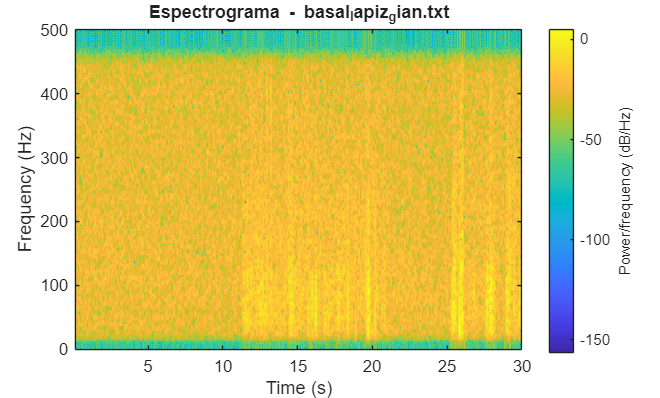

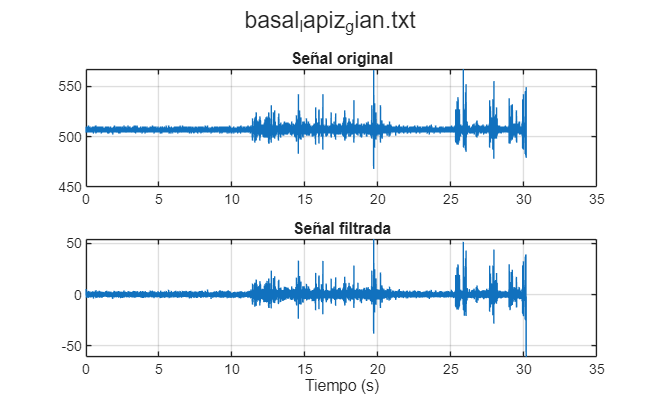


Procesando archivo 8 de 15...


basal_lapiz_noely.txt


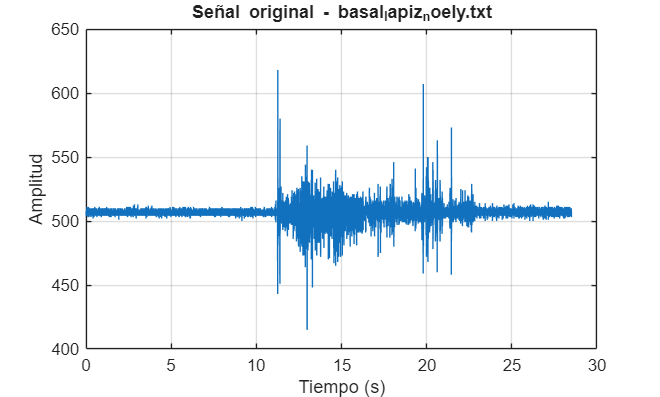

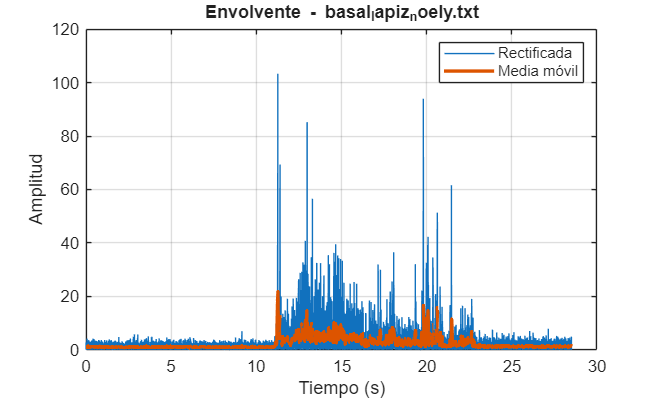

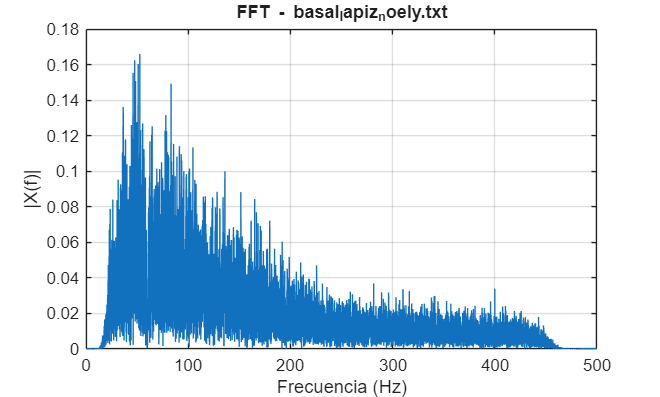

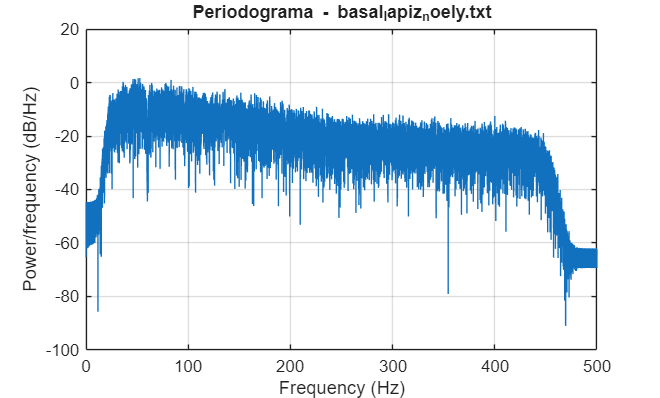

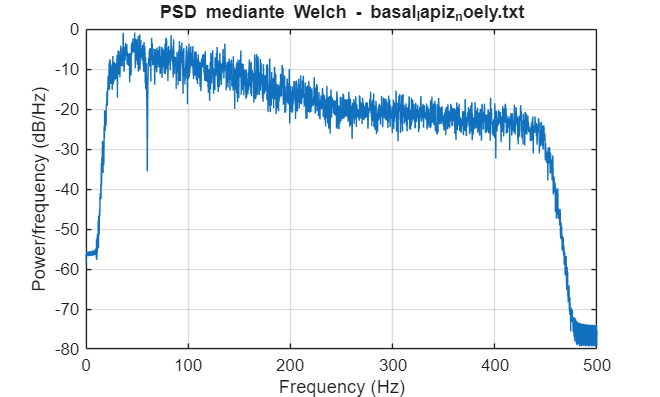

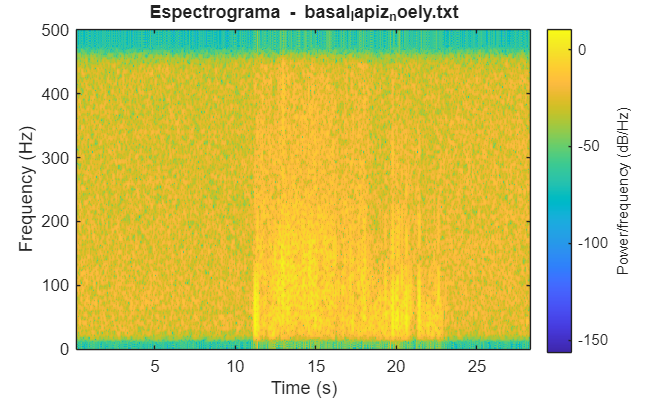

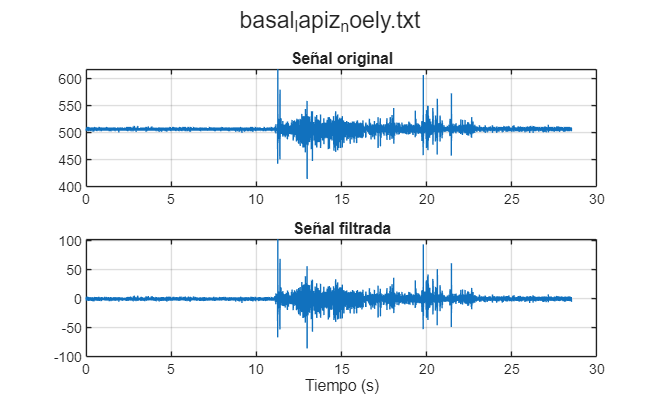


Procesando archivo 9 de 15...


basal_lapizalexander.txt


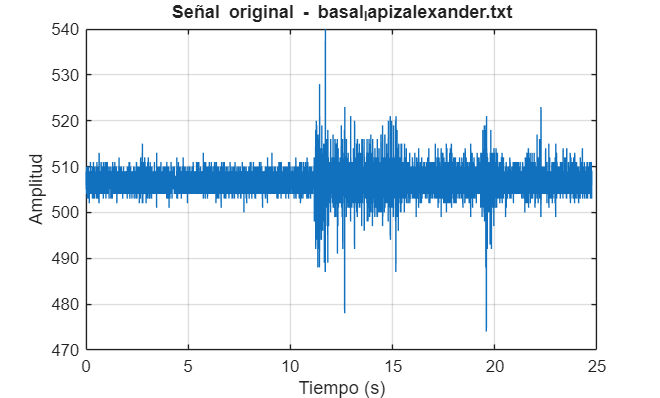

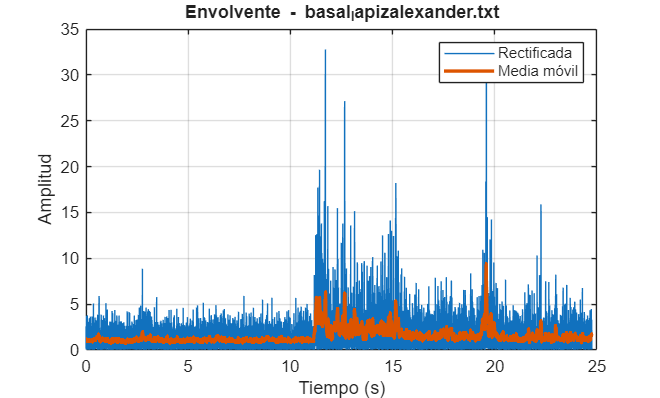

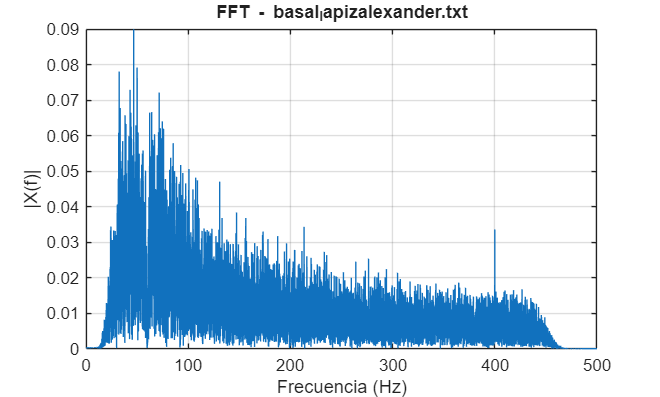

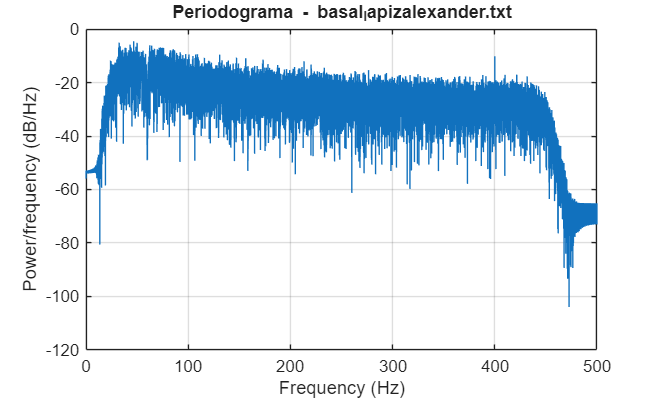

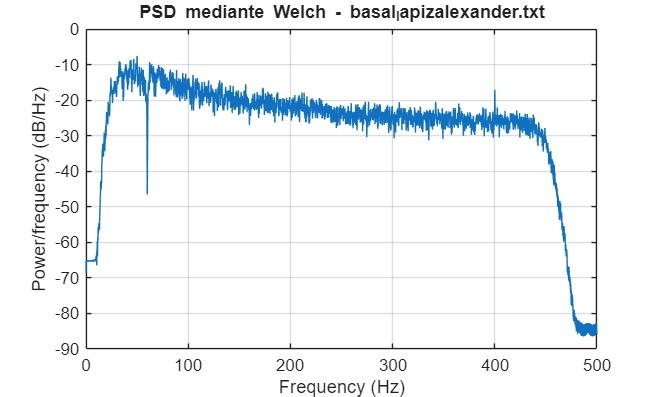

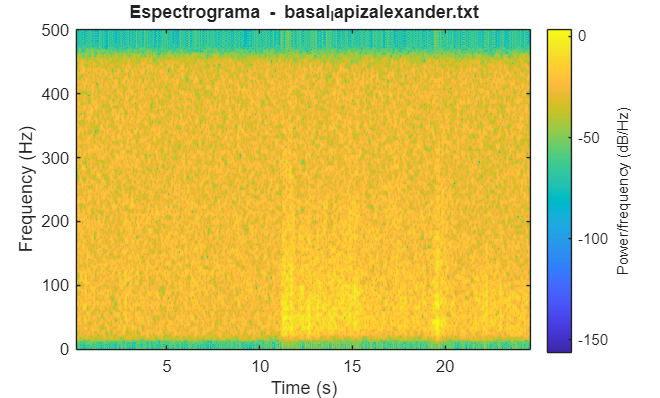

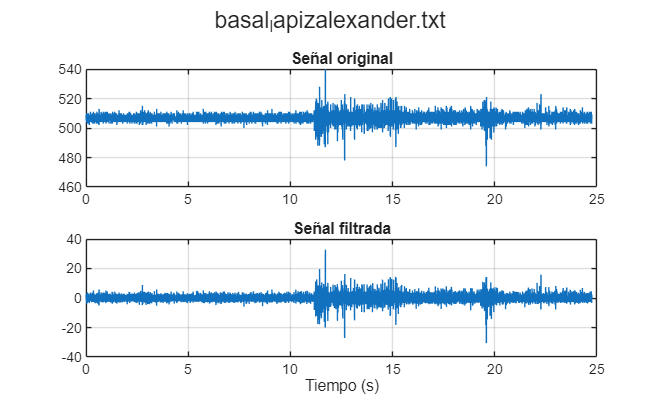


Procesando archivo 10 de 15...


ciromonster15min.txt


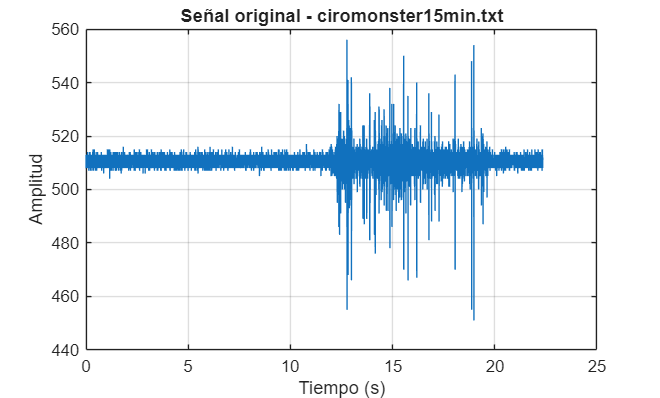

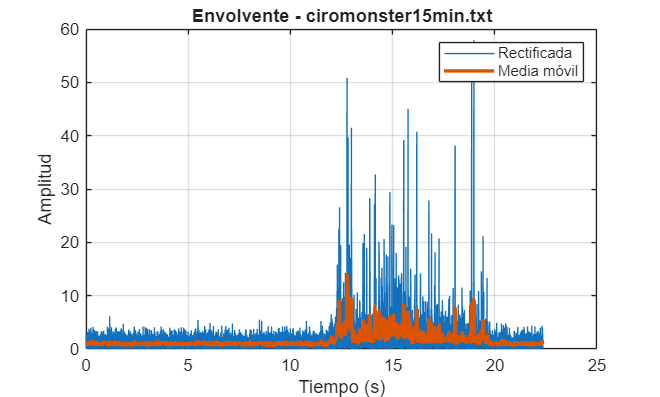

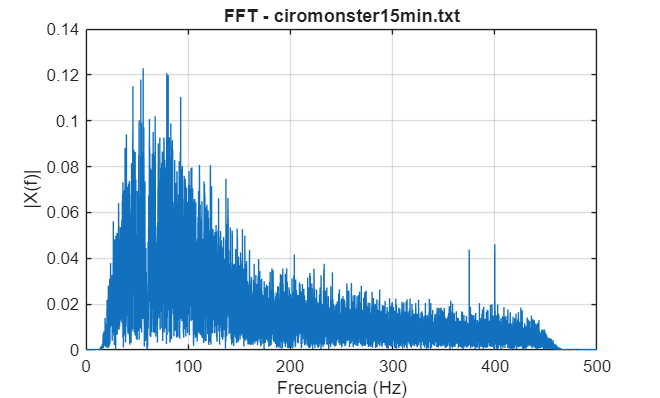

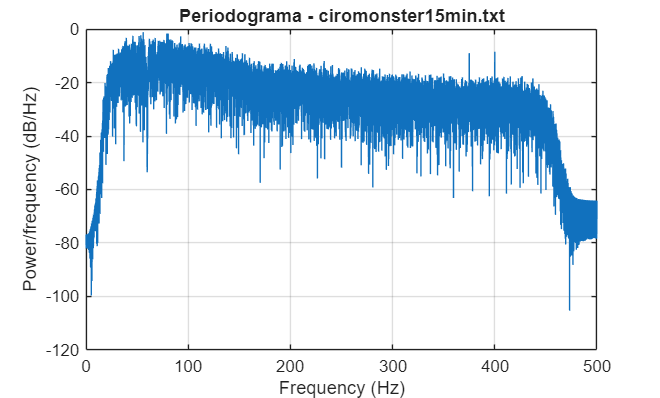

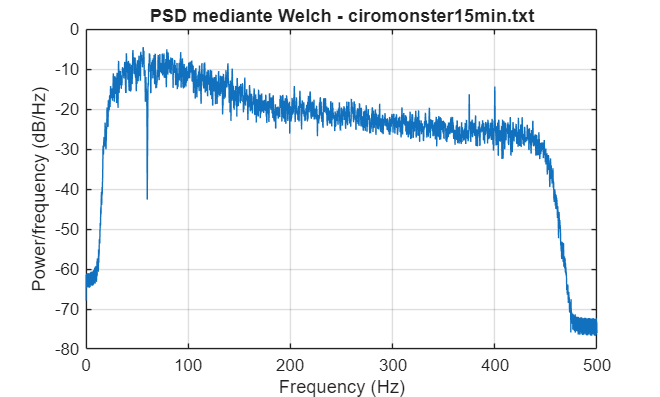

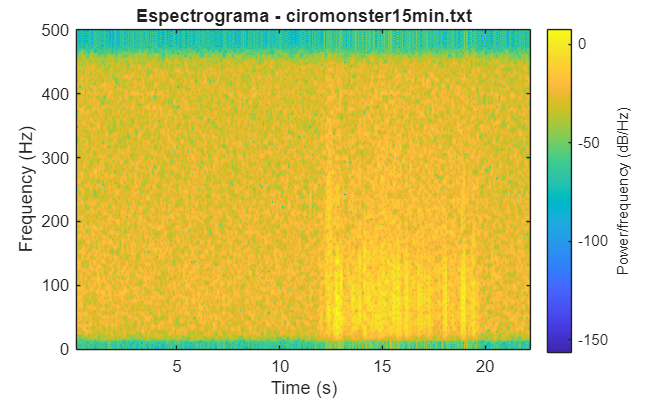

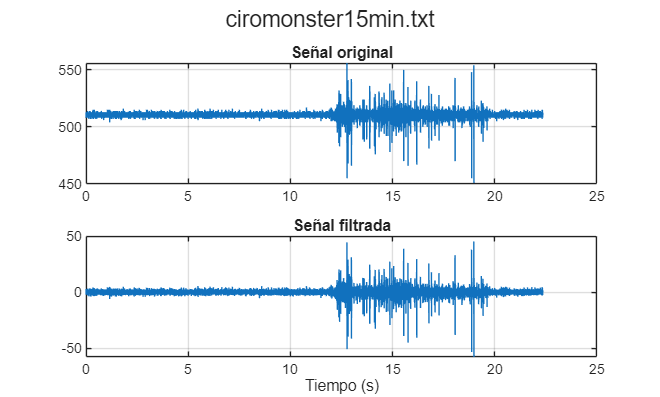


Procesando archivo 11 de 15...


ciromonster1hr.txt


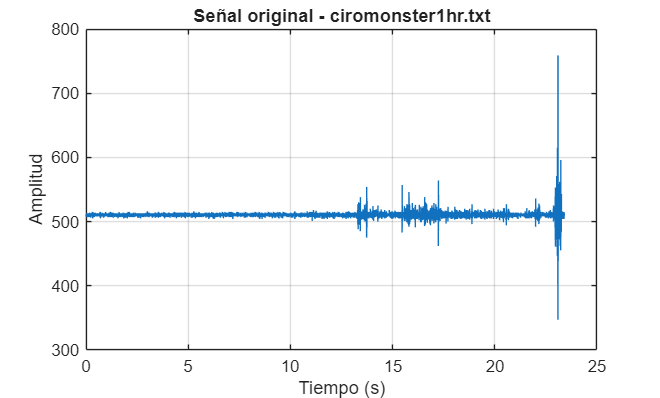

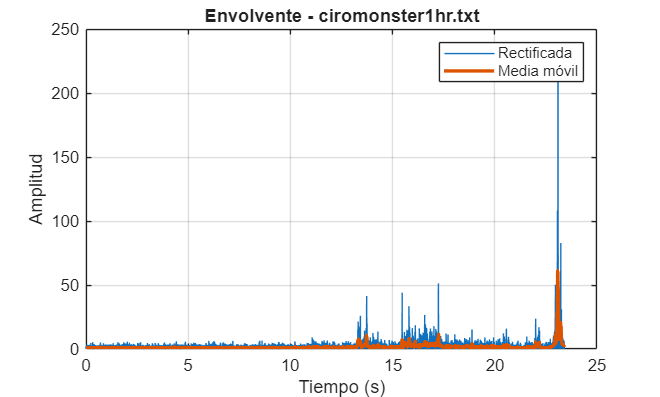

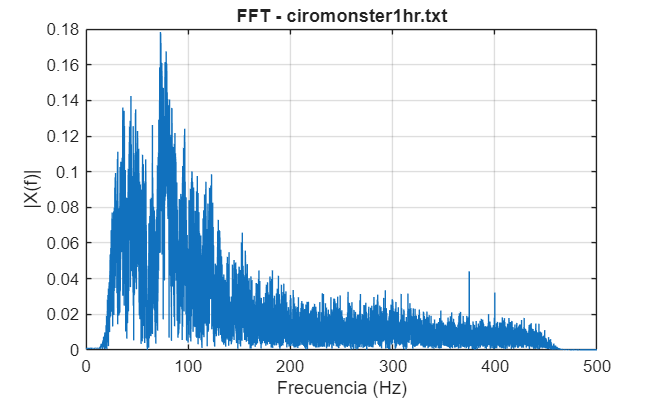

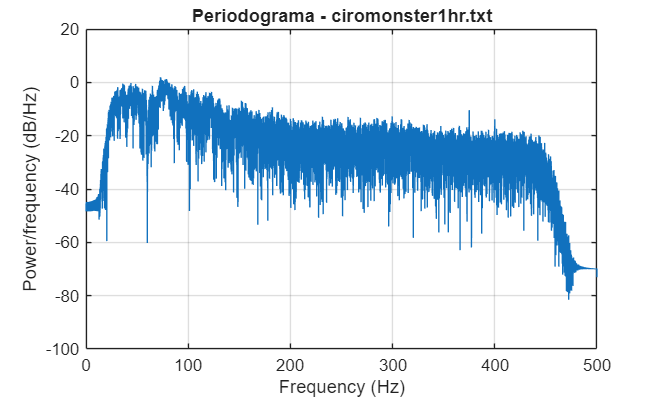

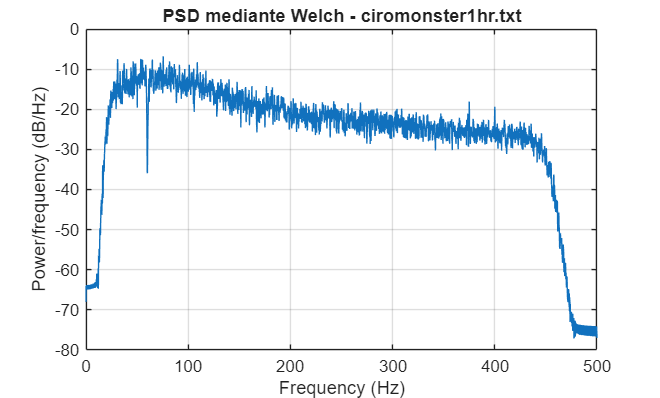

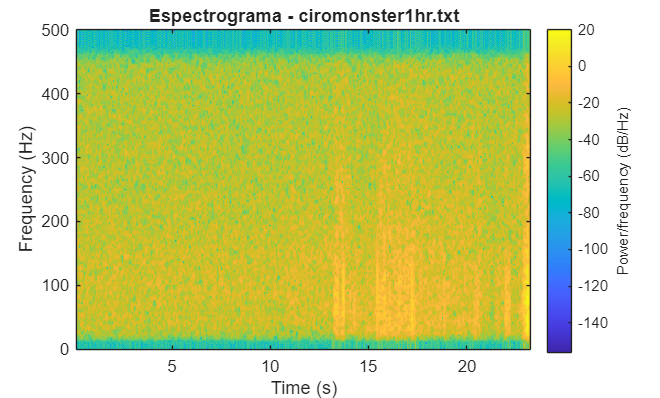

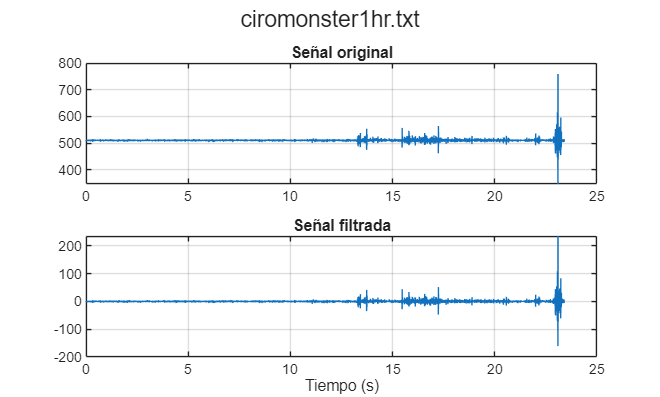


Procesando archivo 12 de 15...


daysimonster15min.txt


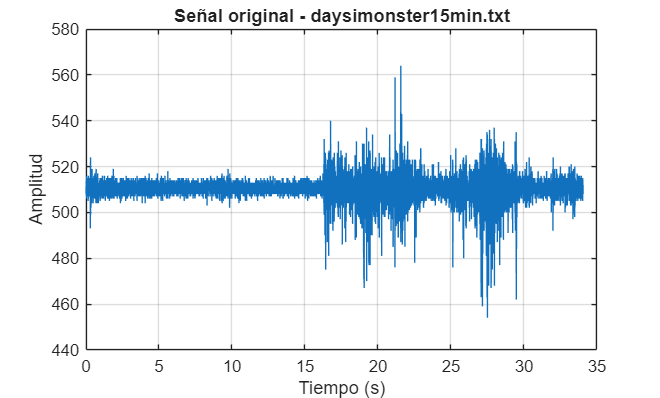

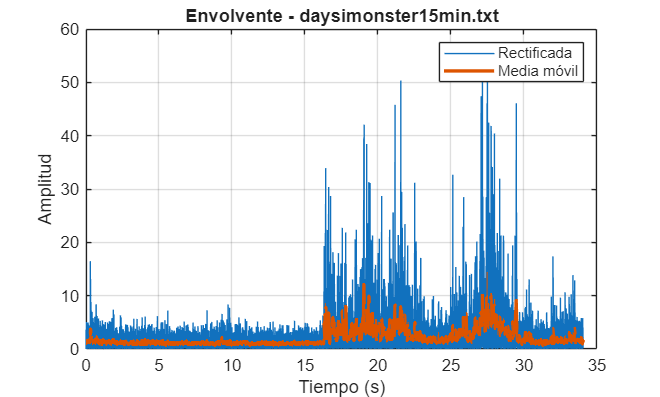

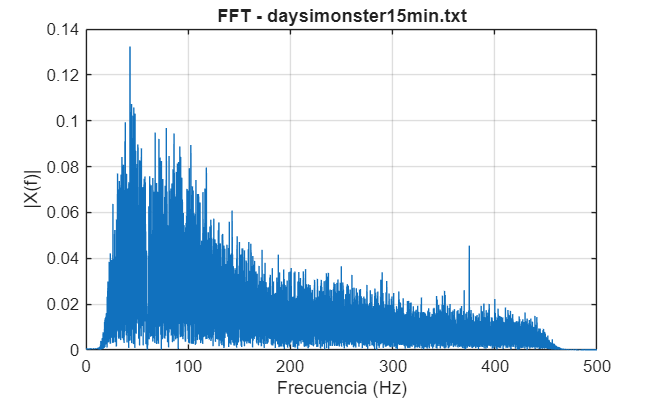

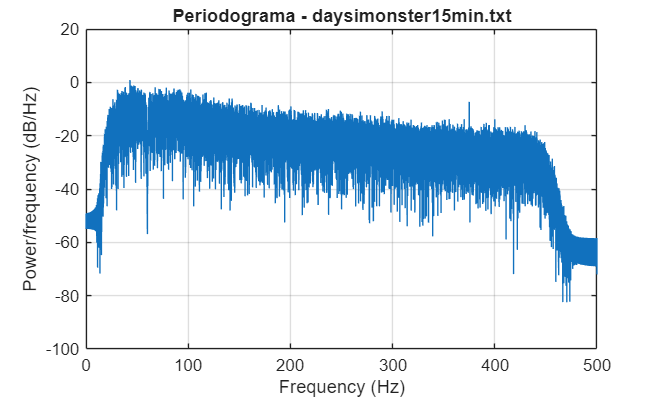

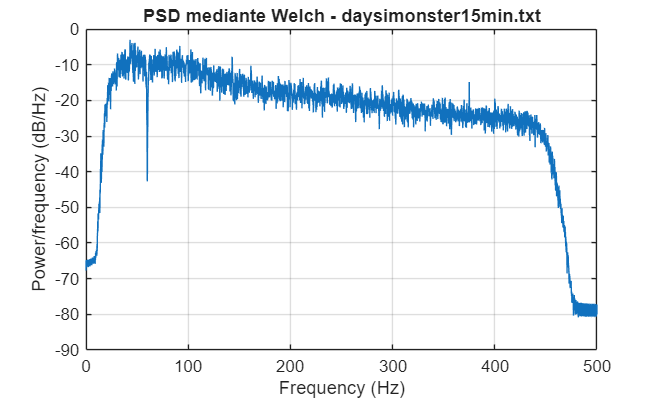

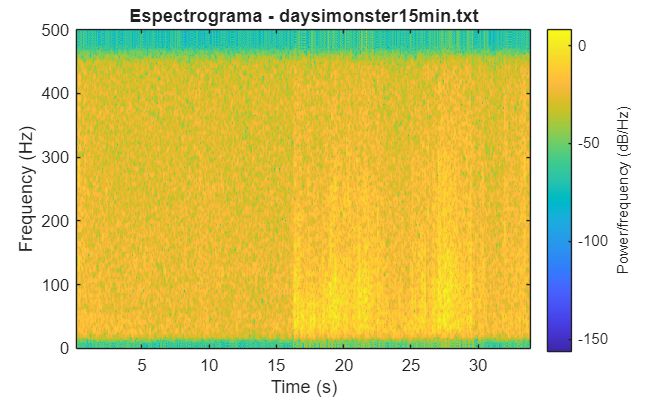

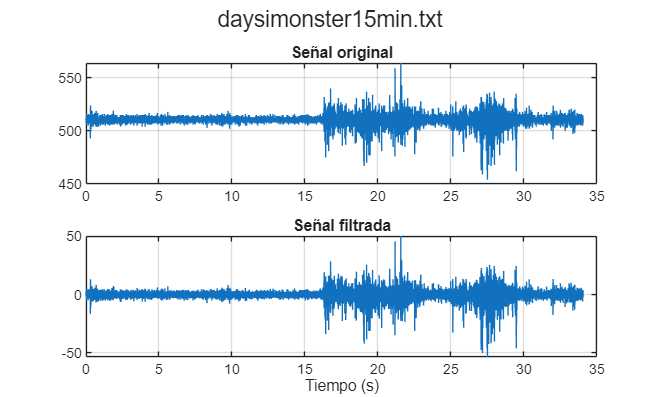


Procesando archivo 13 de 15...


daysimonster1hr.txt


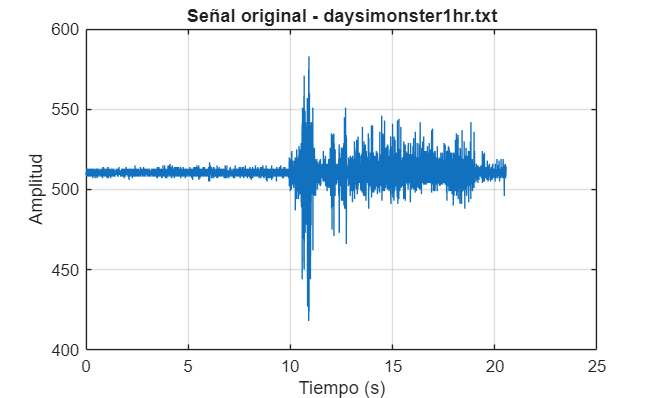

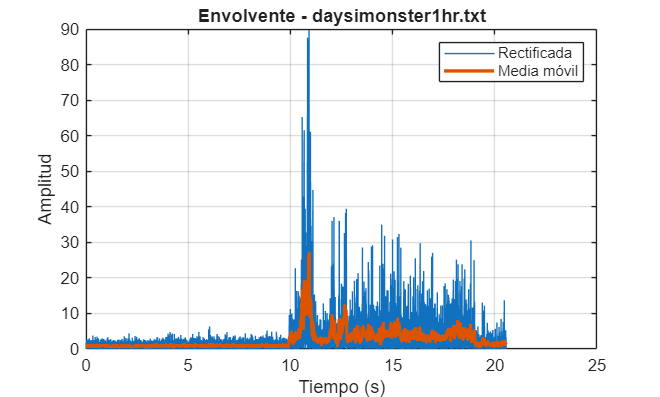

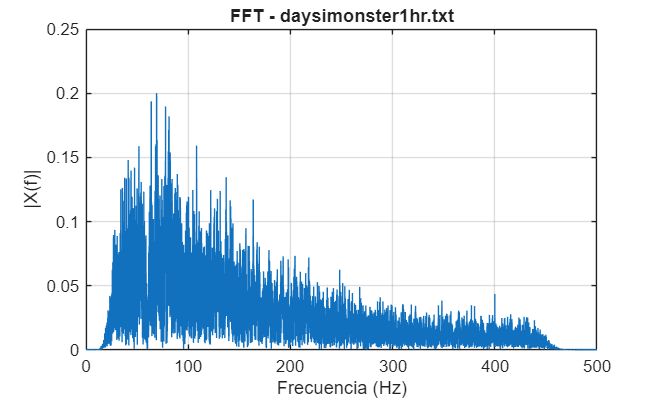

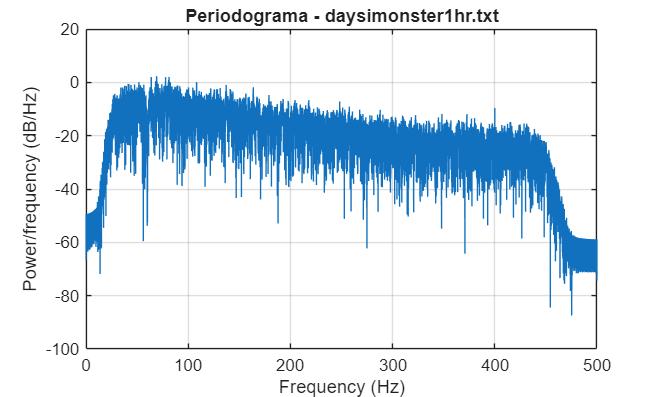

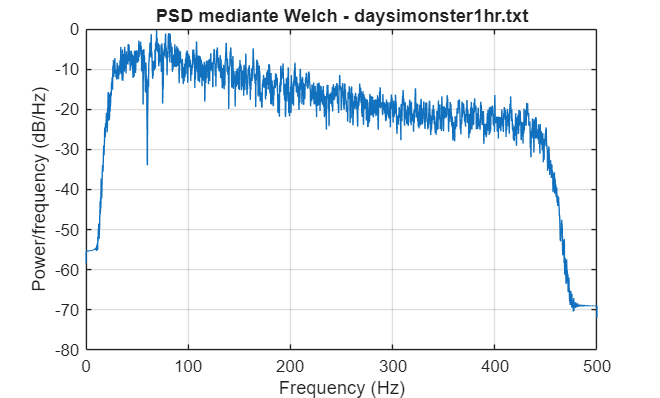

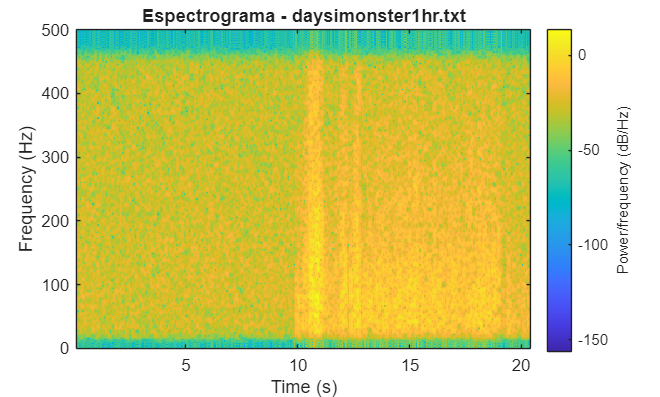

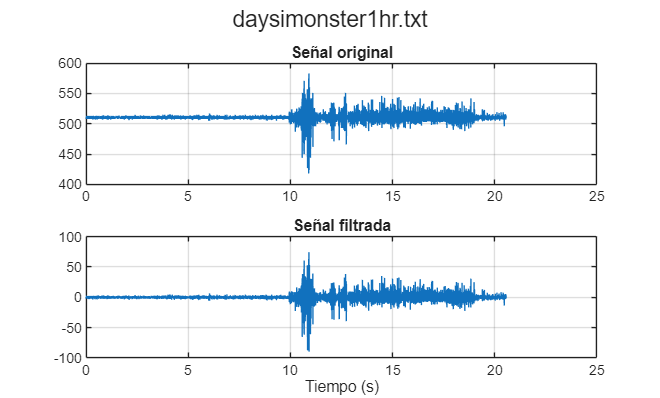


Procesando archivo 14 de 15...


gianmonster15min.txt


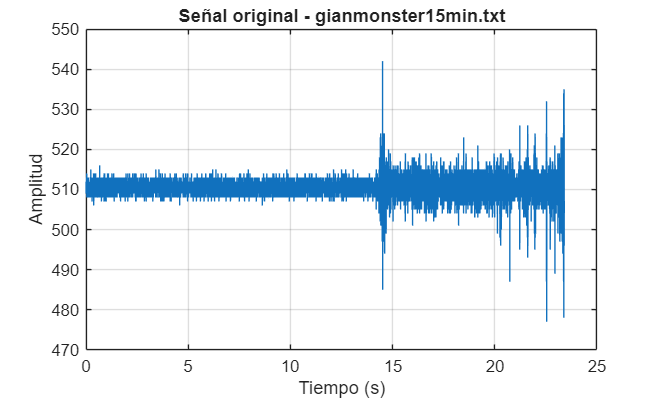

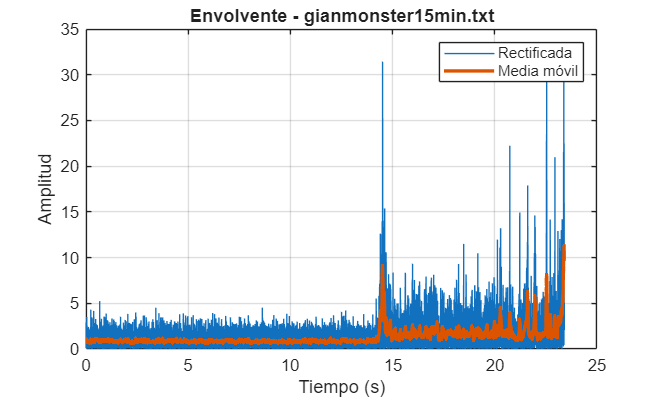

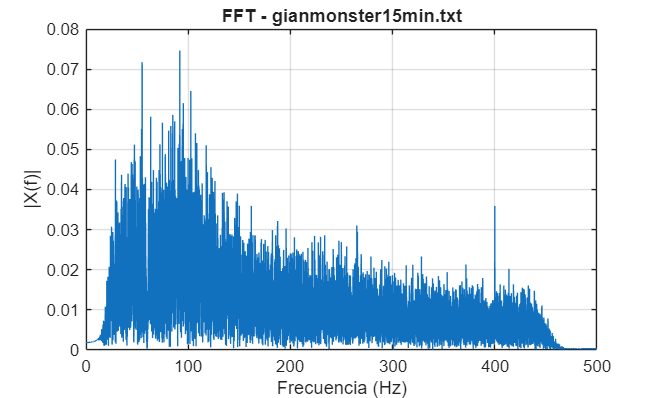

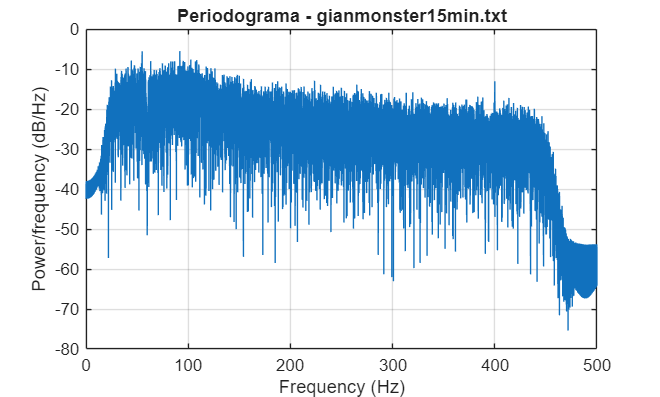

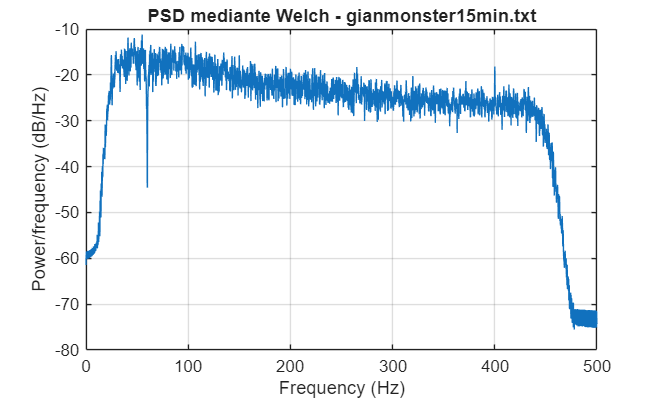

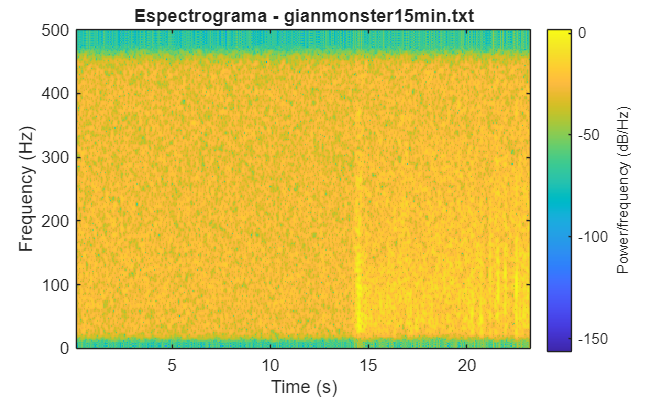

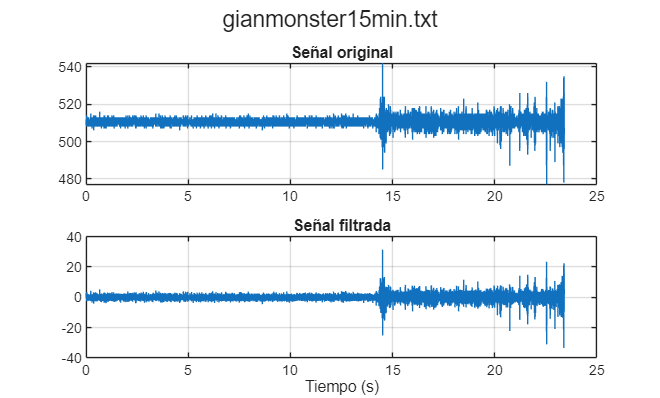


Procesando archivo 15 de 15...


gianmonster1hr.txt


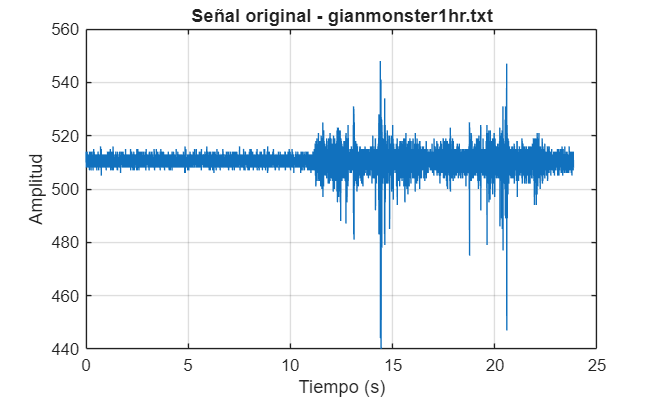

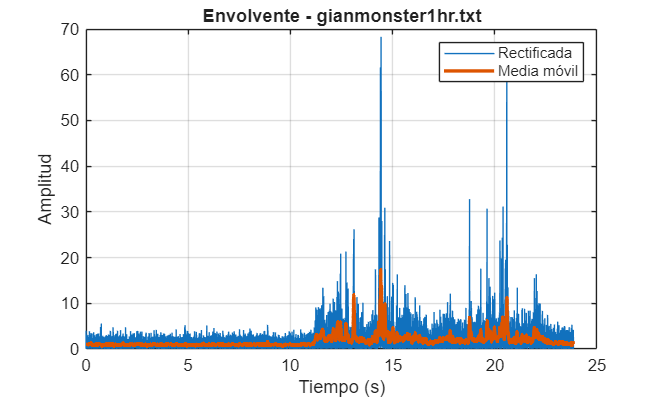

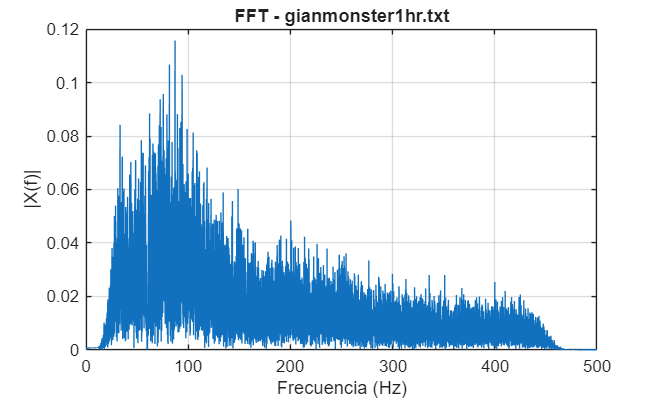

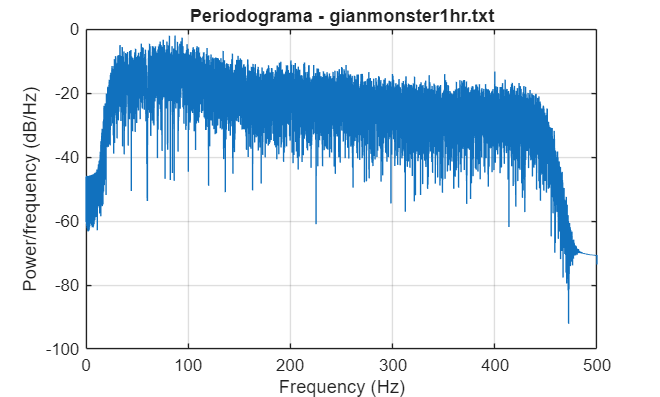

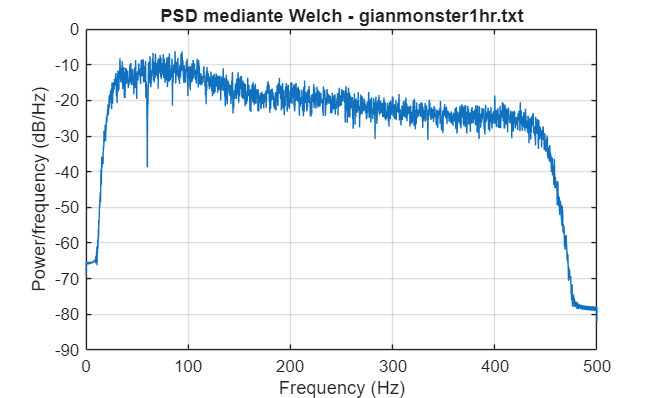

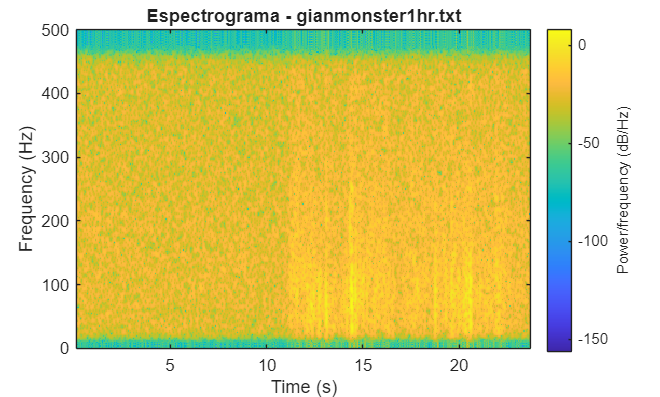

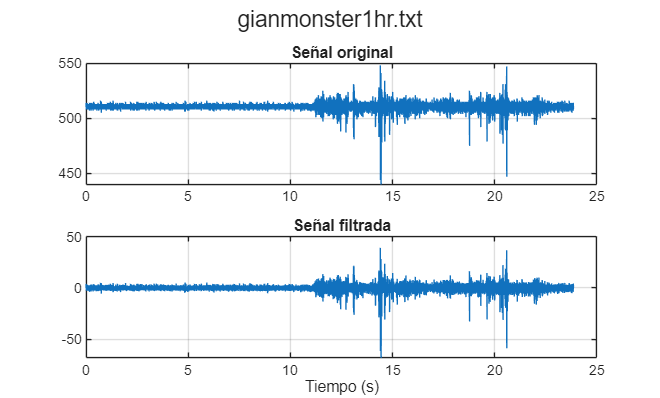

clear; clc;

%=================================================================
%              CARGAMOS LOS DATOS OBTENIDOS DEL BITALINO
%=================================================================

% Seleccionar la carpeta donde están los archivos
carpeta = 'C:\ADRIANO ESTRADA\Intro_senales_biomedicas\PROYECTO_SENIALES';

% Buscar todos los archivos .txt
archivos = dir(fullfile(carpeta, '*.txt'));

% Celda donde se almacenarán los datos
datos = cell(length(archivos),1);

% Nombres de los archivos
nombres = strings(length(archivos),1);

% Leer cada archivo
for k = 1:length(archivos)

    nombreArchivo = fullfile(carpeta, archivos(k).name);

    datos{k} = readmatrix(nombreArchivo,...
                          'FileType','text',...
                          'CommentStyle','#');

    nombres(k) = archivos(k).name;

end

disp('Archivos cargados correctamente.')


%=================================================================
%              PROCESAMIENTO DE SEÑALES
%=================================================================

Fs = 1000; % Se define una frecuencia de muestreo de 1000 Hz

for k = 1:length(datos)

    fprintf('\nProcesando archivo %d de %d...\n',k,length(datos));
    fprintf('%s\n',nombres(k));

    M = datos{k};
    EMG = M(:,6);

    t = (0:length(EMG)-1)/Fs;

    %% ============================================================
    % PREPROCESAMIENTO INTERNO (SIN PLOTEO)
    % ============================================================

    % Eliminación del offset
    EMG0 = EMG - mean(EMG);

    % Filtro Notch (Eliminación del ruido de red eléctrica)
    wo = 60/(Fs/2);
    bw = wo/35;

    [b,a] = iirnotch(wo,bw);

    EMG_notch = filtfilt(b,a,EMG0);

    % Filtro pasabanda (Selección de la banda de interés para un EMG)
    [b,a] = butter(4,[20 450]/(Fs/2),'bandpass');

    EMG_filtrada = filtfilt(b,a,EMG_notch);

    %% ============================================================
    % 1. Señal original
    % ============================================================

    figure;
    plot(t,EMG)
    grid on
    xlabel('Tiempo (s)')
    ylabel('Amplitud')
    title(['Señal original - ' char(nombres(k))])

    saveas(gcf,fullfile(carpeta,...
        erase(nombres(k),".txt")+"_01_Original.png"));

    %% ============================================================
    % 2. Envolvente
    % ============================================================

    EMG_rect = abs(EMG_filtrada);

    ventana = round(0.05*Fs);

    EMG_env = movmean(EMG_rect,ventana);

    figure;
    plot(t,EMG_rect)
    hold on
    plot(t,EMG_env,'LineWidth',2)
    grid on
    legend('Rectificada','Media móvil')
    xlabel('Tiempo (s)')
    ylabel('Amplitud')
    title(['Envolvente - ' char(nombres(k))])

    saveas(gcf,fullfile(carpeta,...
        erase(nombres(k),".txt")+"_02_Envolvente.png"));

    %% ============================================================
    % 3. FFT
    % ============================================================

    N = length(EMG_filtrada);

    Y = fft(EMG_filtrada);

    f = (0:N-1)*(Fs/N);

    P = abs(Y)/N;

    figure;
    plot(f(1:N/2),P(1:N/2))
    grid on
    xlabel('Frecuencia (Hz)')
    ylabel('|X(f)|')
    title(['FFT - ' char(nombres(k))])
    xlim([0 500])

    saveas(gcf,fullfile(carpeta,...
        erase(nombres(k),".txt")+"_03_FFT.png"));

    %% ============================================================
    % 4. Periodograma
    % ============================================================

    figure;
    periodogram(EMG_filtrada,[],[],Fs)

    title(['Periodograma - ' char(nombres(k))])

    saveas(gcf,fullfile(carpeta,...
        erase(nombres(k),".txt")+"_04_Periodograma.png"));

    %% ============================================================
    % 5. Welch
    % ============================================================

    figure;
    pwelch(EMG_filtrada,[],[],[],Fs)

    title(['PSD mediante Welch - ' char(nombres(k))])

    saveas(gcf,fullfile(carpeta,...
        erase(nombres(k),".txt")+"_05_Welch.png"));

    %% ============================================================
    % 6. Espectrograma
    % ============================================================

    figure;
    spectrogram(EMG_filtrada,...
                hamming(256),...
                200,...
                512,...
                Fs,...
                'yaxis')

    title(['Espectrograma - ' char(nombres(k))])

    saveas(gcf,fullfile(carpeta,...
        erase(nombres(k),".txt")+"_06_Espectrograma.png"));

    %% ============================================================
    % 7. Comparación (Modificación de la señal Original para análsis)
    % ============================================================

    figure

    subplot(2,1,1)
    plot(t,EMG)
    grid on
    title('Señal original')

    subplot(2,1,2)
    plot(t,EMG_filtrada)
    grid on
    title('Señal filtrada')
    xlabel('Tiempo (s)')

    sgtitle(char(nombres(k)))

    saveas(gcf,fullfile(carpeta,...
        erase(nombres(k),".txt")+"_07_Comparacion.png"));

end